# **Chapter 8: Root Locus Techniques**

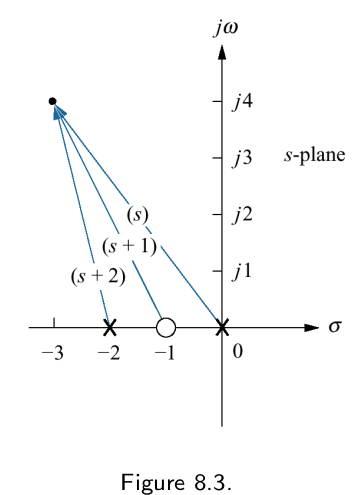

Evaluate $F(s) = \frac{(s+1)}{s(s+2)}$  at $s = -3 +j4$

F=zpk([-1],[0 -2],1)

F =
 
   (s+1)
  -------
  s (s+2)
 
Continuous-time zero/pole/gain model.



s1=-3+4*j

s1 = -3.0000 + 4.0000i

evalfr(F,s1)

ans = -0.0894 - 0.1976i

abs(evalfr(F,s1))

ans = 0.2169

abs(s1+1)/(abs(s1)*abs(s1+2))

ans = 0.2169

angle(evalfr(F,s1))

ans = -1.9956

angle(s1+1)-angle(s1)-angle(s1+2)

ans = -1.9956

180/pi*(angle(s1+1)-angle(s1)-angle(s1+2))

ans = -114.3411

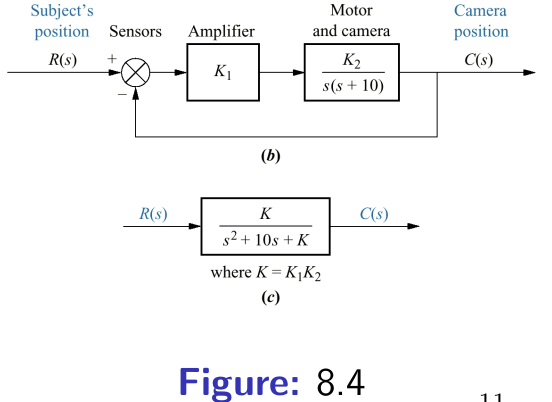

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=1/(s*(s+10))

G =
 
      1
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.



pole(feedback(25*G,1))

ans =     -5
    -5


pole(feedback(50*G,1))

ans =   -5.0000 + 5.0000i
  -5.0000 - 5.0000i


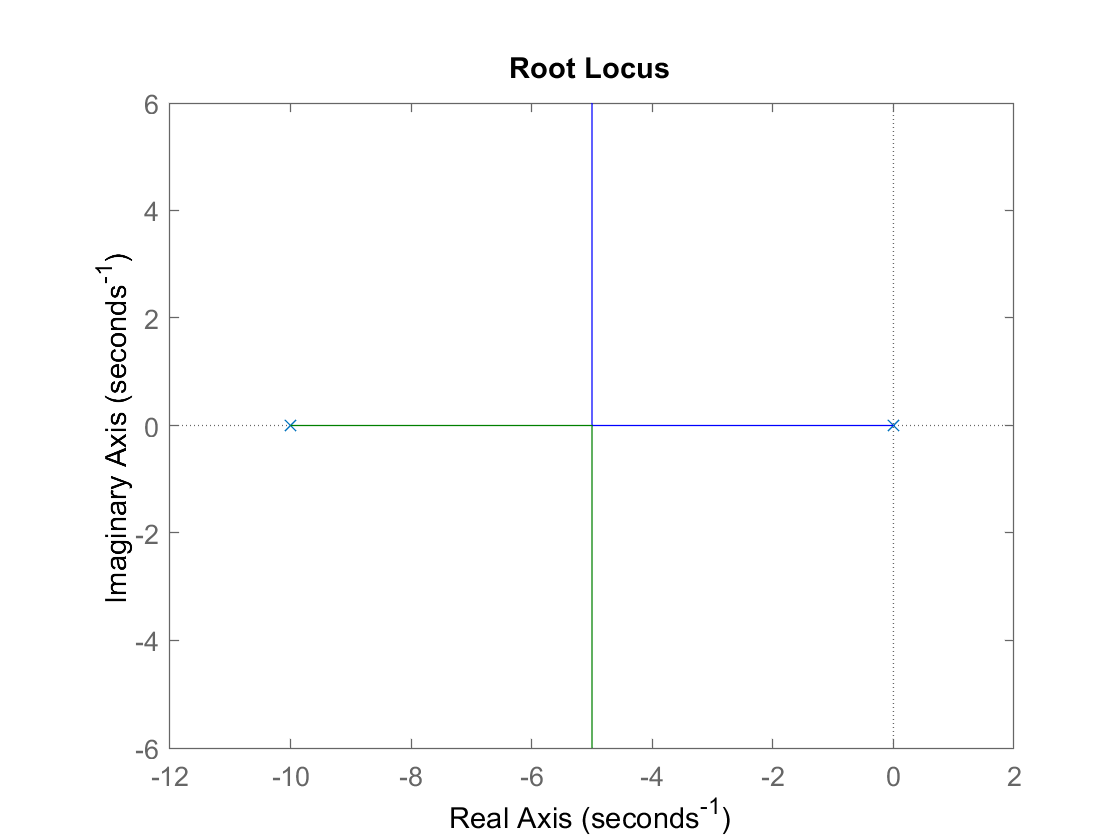

rlocus(G)

For system below, consider $s=-2+j3$ and $s=-2+j\frac{\sqrt{2}}{2}$

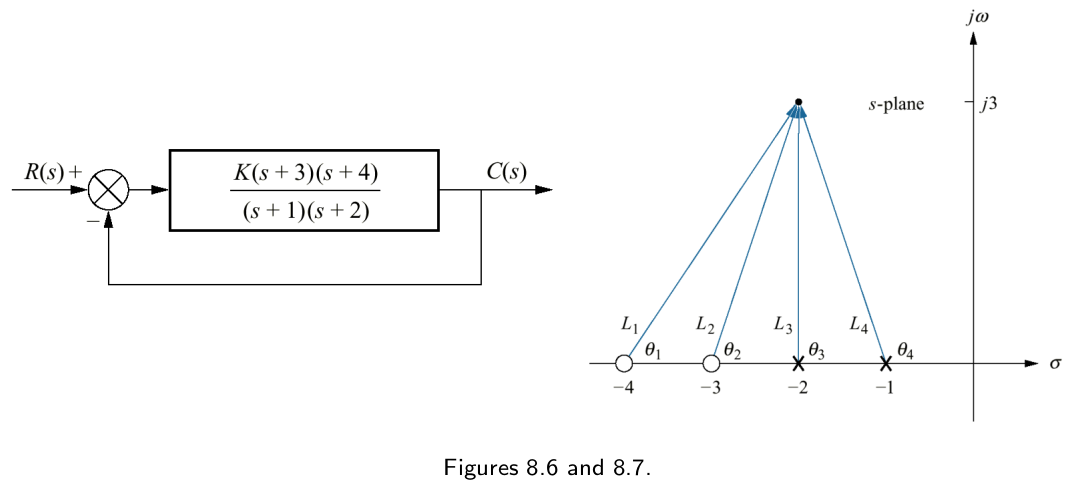

G=zpk([-3 -4],[-1 -2],1)

G =
 
  (s+3) (s+4)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



evalfr(G,-2+j*3)

ans = 0.4000 - 1.1333i

angle(evalfr(G,-2+j*3))*180/pi

ans = -70.5600

So $G(-2+j3)$ does not lie on the negative real axis so there is no value of $K$ for which $G_\textit{cl}(s)=\frac{K*G(s)}{1+K*G(s)}$ has poles at $s=-2+j3$

On the other hand for $s=-2+j\frac{\sqrt{2}}{2}$

evalfr(G,-2+j*1/sqrt(2))

ans = -3.0000 + 0.0000i

angle(evalfr(G,-2+j*1/sqrt(2)))*180/pi

ans = 180

so there exists a value of $K$ for which the closed loop system will have poles at $s=-2\pm j\frac{\sqrt{2}}{2}$ and that value is 


$$K=\frac{1}{\left |G\left (-2+j\frac{\sqrt{2}}{2}\right )\right |}$$


K=1/abs(evalfr(G,-2+j*1/sqrt(2)))

K = 0.3333

Thus $1+KG\left (-2+j\frac{\sqrt{2}}{2}\right )=1+\frac{1}{3}(-3)=0$ so $s=-2+j\frac{\sqrt{2}}{2}$ is a pole of the closed loop system when $K=\frac{1}{3}$. Lets check this numerically to confirm.

G_cl=feedback(K*G,1)

G_cl =
 
  0.25 (s+3) (s+4)
  ----------------
  (s^2 + 4s + 4.5)
 
Continuous-time zero/pole/gain model.



pole(G_cl)

ans =   -2.0000 + 0.7071i
  -2.0000 - 0.7071i


Let's do the angle check shown in figure 8.7 above:

s1=-2+j*1/sqrt(2)

s1 = -2.0000 + 0.7071i

theta_1=angle(s1+4)*180/pi

theta_1 = 19.4712

theta_2=angle(s1+3)*180/pi

theta_2 = 35.2644

theta_3=angle(s1+2)*180/pi

theta_3 = 90

theta_4=angle(s1+1)*180/pi

theta_4 = 144.7356

theta=theta_1+theta_2-theta_3-theta_4

theta = -180.0000

Let's plot the root locus and confirm that $s=-2+j3$ does not lie on the root locus and $s=-2+\frac{\sqrt{2}}{2}$ does lie on the root locus

rlocus(G)
hold

Current plot held


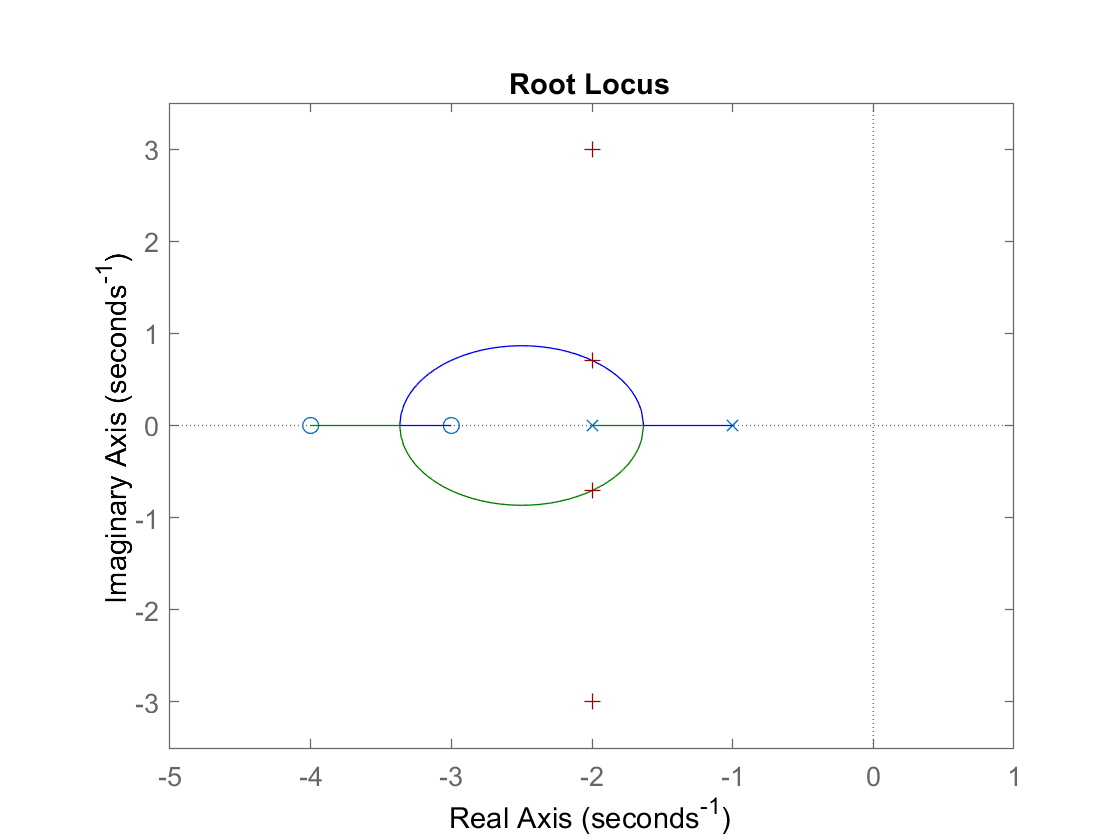

Current plot released


plot([-2+j*3 -2-j*3 -2+j*1/sqrt(2) -2-j*1/sqrt(2)], '+','Color',[.6 0 0])
ylim([-3.5 3.5])
hold

Sketch the root locus for system below.

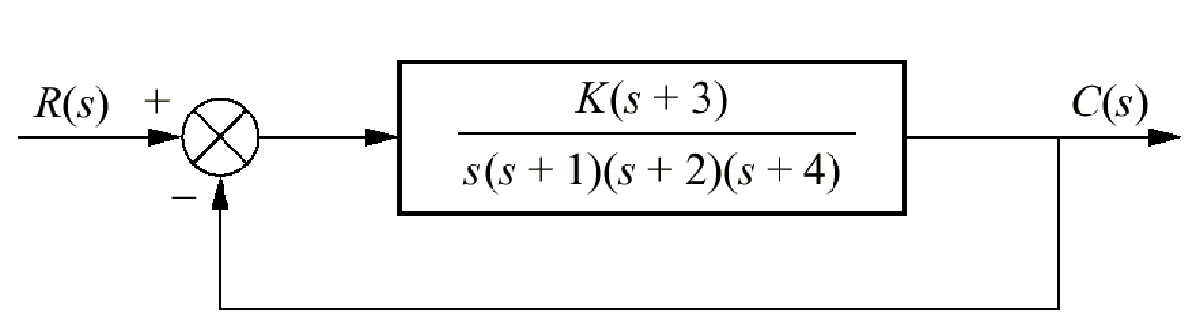

G=zpk([-3],[0 -1 -2 -4],1)


$$\sigma_a = \frac{\Sigma \mbox{finite poles} - \Sigma \mbox{finite zeros}}{\# \mbox{finite poles}- \# \mbox{finite zeros}}\\
\ \ =\frac{0+(-1)+(-2)+(-4)-(-3)}{4-1}\\
\ \ =\frac{-4}{3}\\
\theta_a = \frac{(2k+1)\pi}{\# \mbox{finite poles}- \# \mbox{finite zeros}}\\
\ \ = \frac{(2k+1)\pi}{4-1}\\
\ \ = -\frac{ \pi}{3}, \frac{ \pi}{3}, \pi, \mbox{ for } k=-1,0,1$$


sigma_a=(0-1-2-4+3)/(4-1)

sigma_a = -1.3333

Or computing sigma automatically from the Matlab numerical transfer function:

[p,z]=pzmap(G)
sigma_a=(sum(p)-sum(z))/(length(p)-length(z))

G =
 
         (s+3)
  -------------------
  s (s+1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



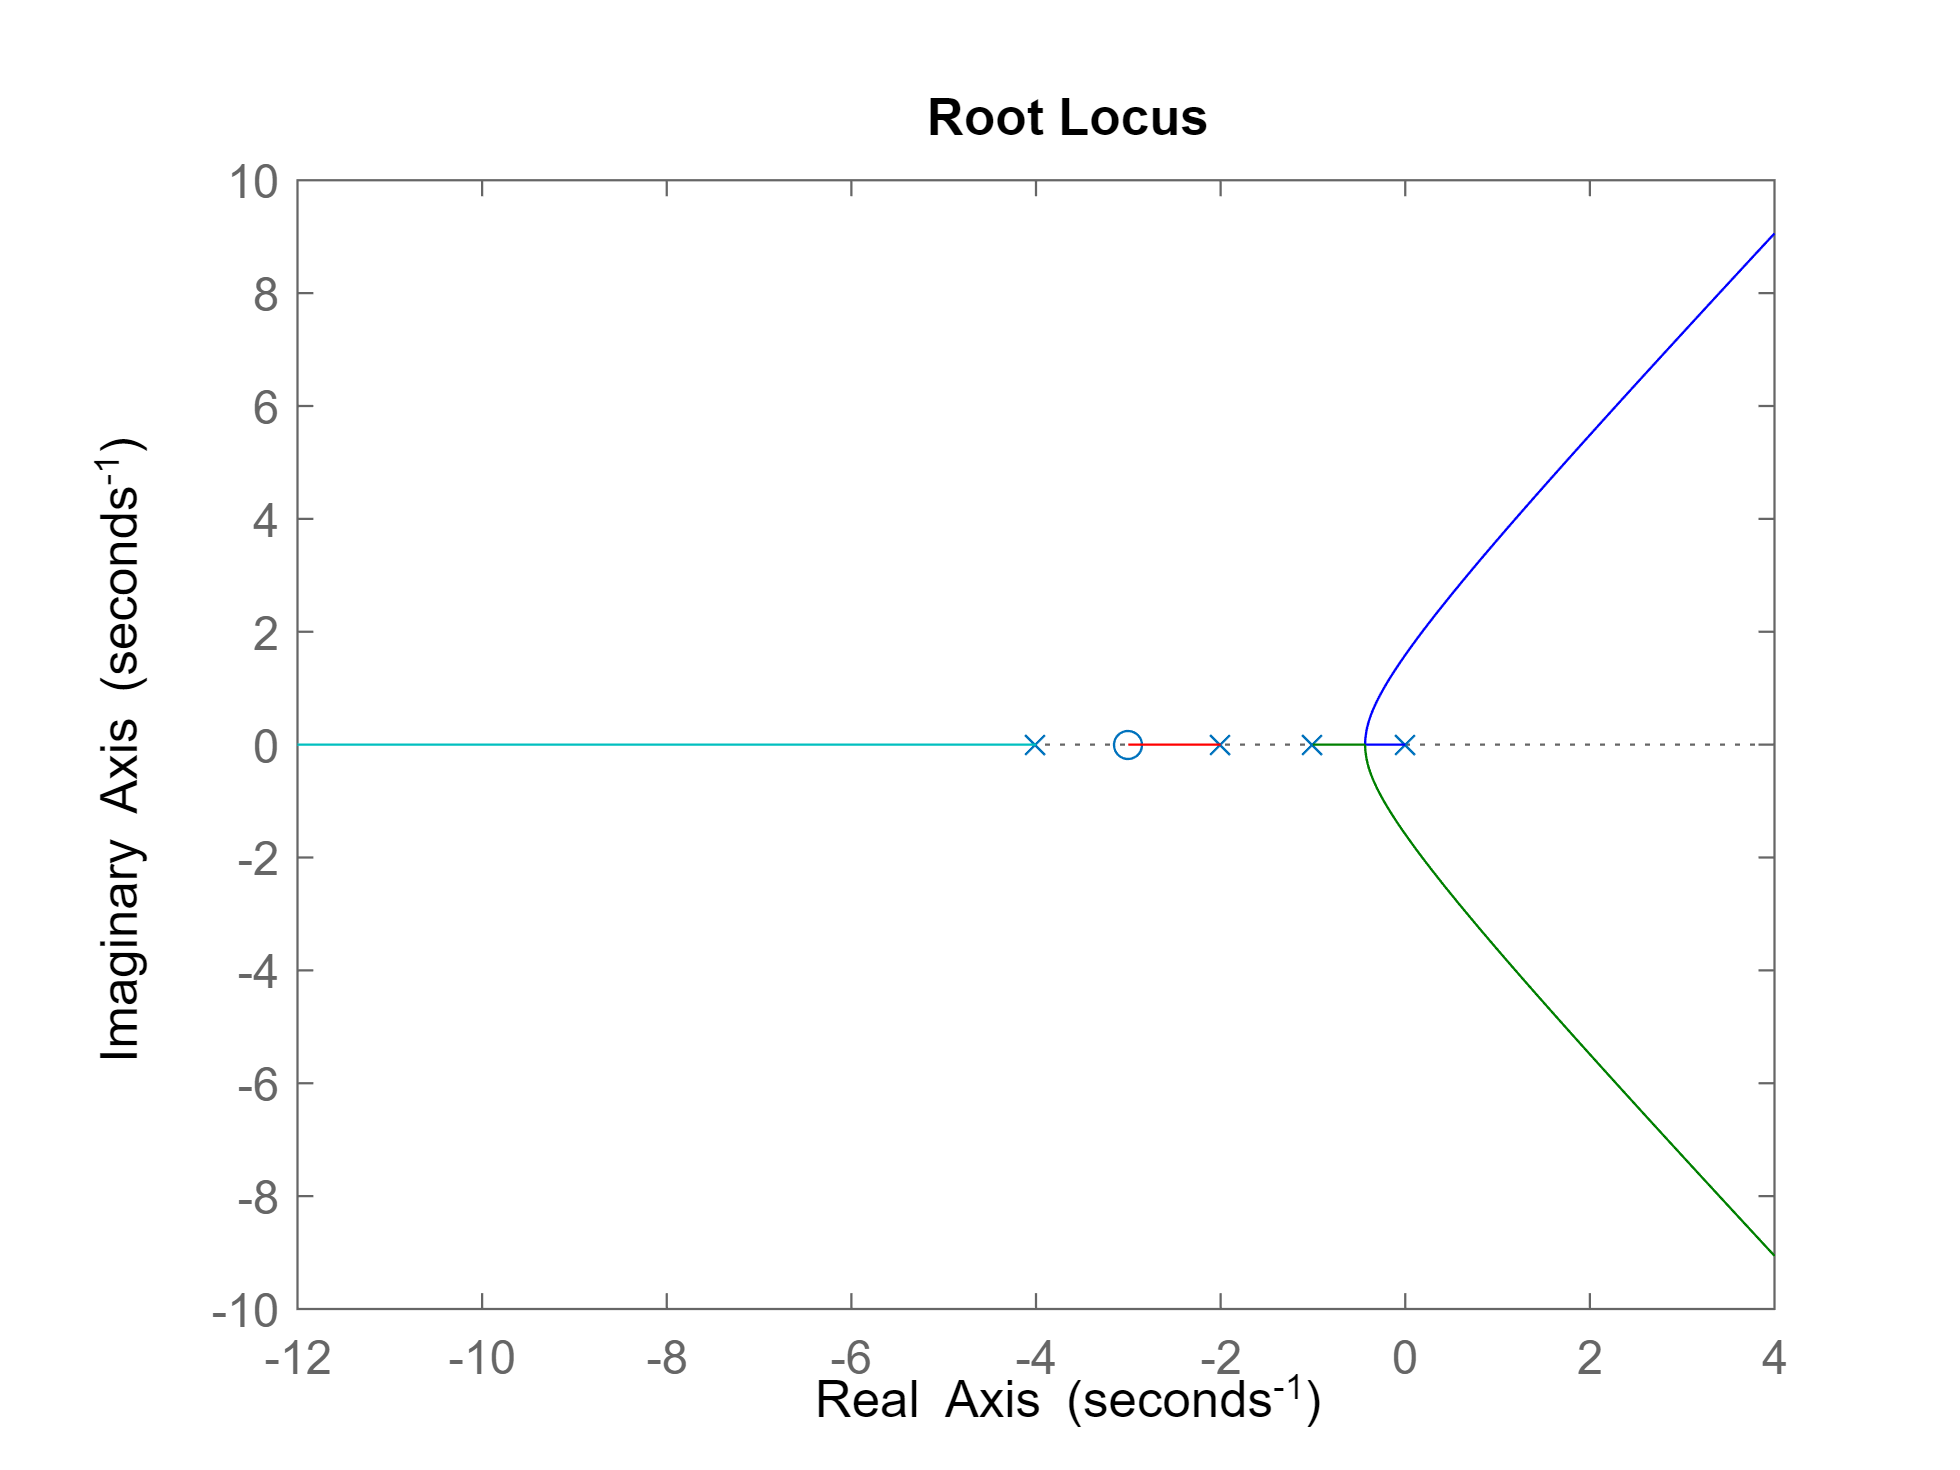

rlocus(G)

### Real-axis Breakaway and Break-in Points

Consider the root locus for $G(s)=\frac{(s-3)(s-5)}{(s+1)(s+2)}$

G=zpk([3 5],[-1 -2],1)

G =
 
  (s-3) (s-5)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



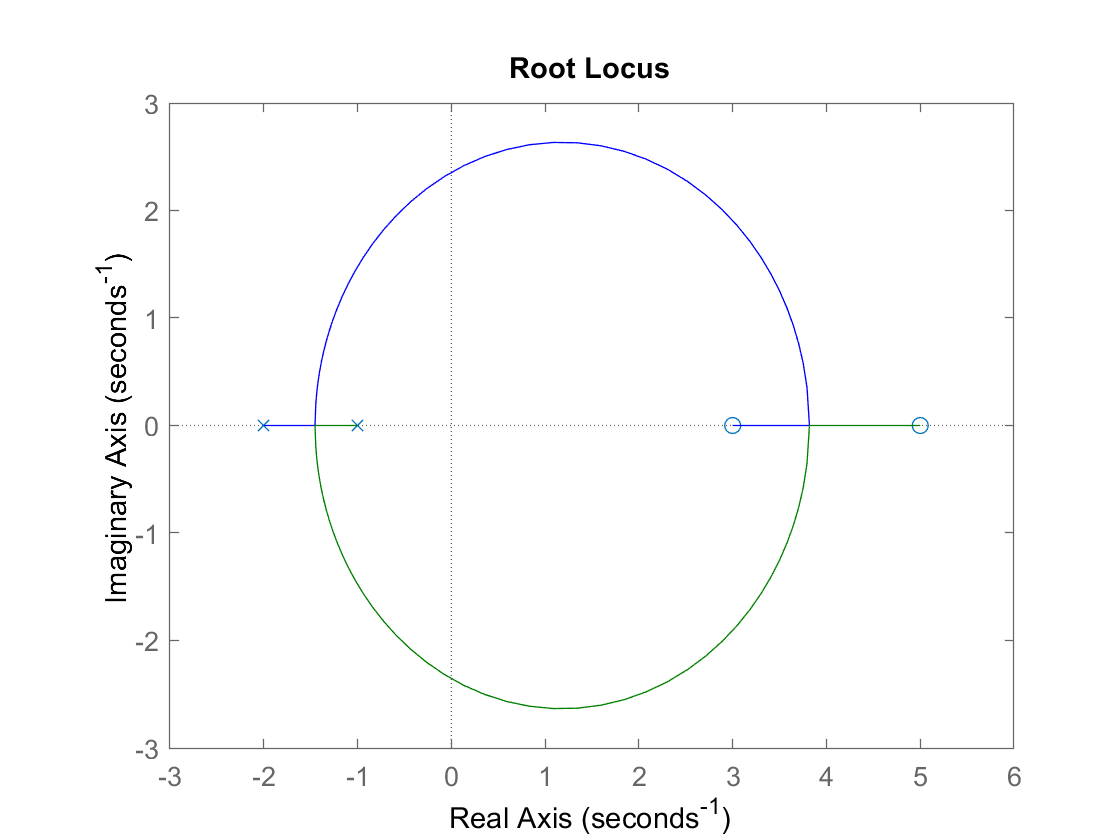

rlocus(G)

How can we determine where bewteen -1 and -2 does the root locus leave the negative real axis (breakaway) and where does it return to the postitive real axis (break-in) between 3 and 5? 

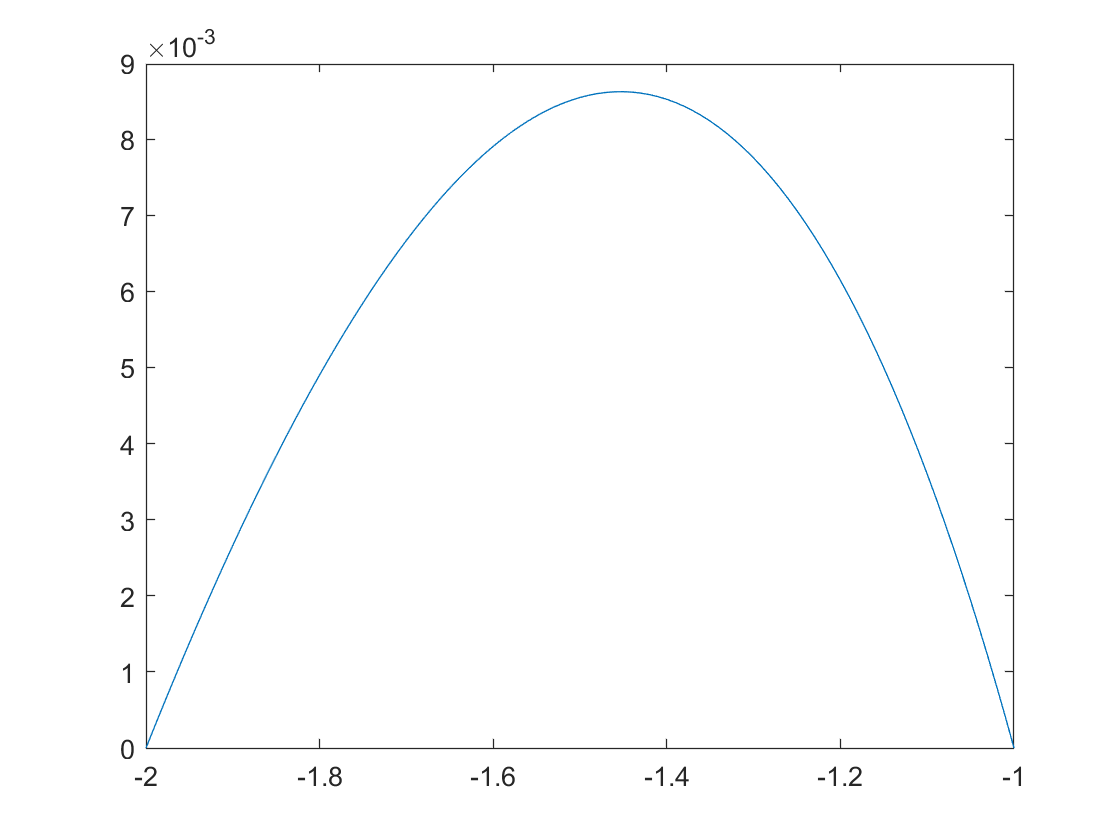

sigma=-2:.01:-1;
K=-(sigma+1).*(sigma+2)./((sigma-3).*(sigma-5));
plot(sigma,K)

So we can see that there is a maximum value of $K$ for some $\sigma$ such that $-1.6 < \sigma < -1.4$.

Similarly for $\sigma$ between 3 and 5 where the root locus "breaks in" to the real axis (ie. closed loop poles before real valued again, we see

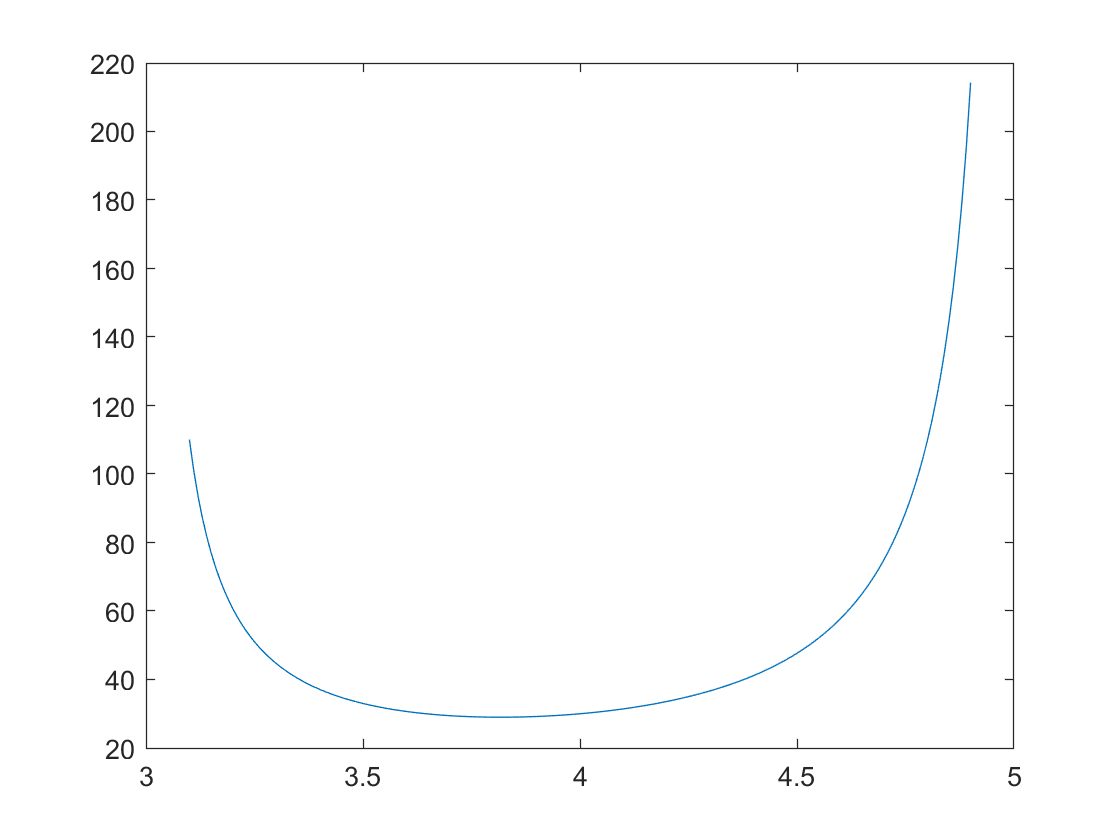

sigma=3.1:.01:4.9;
K=-(sigma+1).*(sigma+2)./((sigma-3).*(sigma-5));
plot(sigma,K)

a minimum at some $\sigma$ such that $3.5 < \sigma <4$. 

We can solve for these points analytically as follows

clear
syms sigma s K 
G=(s-3)*(s-5)/((s+1)*(s+2))

$$G = \frac{\left(s-3\right)\,\left(s-5\right)}{\left(s+1\right)\,\left(s+2\right)}$$

eq1=1+K*G==0

$$eq1 = \frac{K\,\left(s-3\right)\,\left(s-5\right)}{\left(s+1\right)\,\left(s+2\right)}+1=0$$

eq2=isolate(eq1,K)

$$eq2 = K=-\frac{\left(s+1\right)\,\left(s+2\right)}{\left(s-3\right)\,\left(s-5\right)}$$

eq2=subs(eq2,s,sigma)

$$eq2 = K=-\frac{\left(\sigma +1\right)\,\left(\sigma +2\right)}{\left(\sigma -3\right)\,\left(\sigma -5\right)}$$

dK=diff(rhs(eq2),1)

$$dK = \frac{\left(\sigma +1\right)\,\left(\sigma +2\right)}{\left(\sigma -3\right)\,{\left(\sigma -5\right)}^{2}}-\frac{\sigma +2}{\left(\sigma -3\right)\,\left(\sigma -5\right)}-\frac{\sigma +1}{\left(\sigma -3\right)\,\left(\sigma -5\right)}+\frac{\left(\sigma +1\right)\,\left(\sigma +2\right)}{{\left(\sigma -3\right)}^{2}\,\left(\sigma -5\right)}$$

dk=simplifyFraction(dK)

$$dk = -\frac{-11\,\sigma^{2}+26\,\sigma +61}{{\left(\sigma -3\right)}^{2}\,{\left(\sigma -5\right)}^{2}}$$

points=solve(diff(rhs(eq2),1)==0)

$$points = \left(\begin{array}{c} \frac{13}{11}-\frac{2\,\sqrt{210}}{11}\\ \frac{2\,\sqrt{210}}{11}+\frac{13}{11} \end{array}\right)$$

double(points)

ans =    -1.4530
    3.8166


Let's just check that bother of these points lie on the root locus by checking that when we evaluate the open loop transfer function at those values they have an angle that is an odd multiple of $\pi$ radians or $180^\circ$ (ie. they result in negative real values).

double(subs(G,s,points(1)))

ans = -115.9655

double(subs(G,s,points(2)))

ans = -0.0345

Now lets plot those points on the root locus and see if they correspond to the breakout and breakin points.

G=zpk([3 5],[-1 -2],1)

G =
 
  (s-3) (s-5)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



rlocus(G)
hold

Current plot held


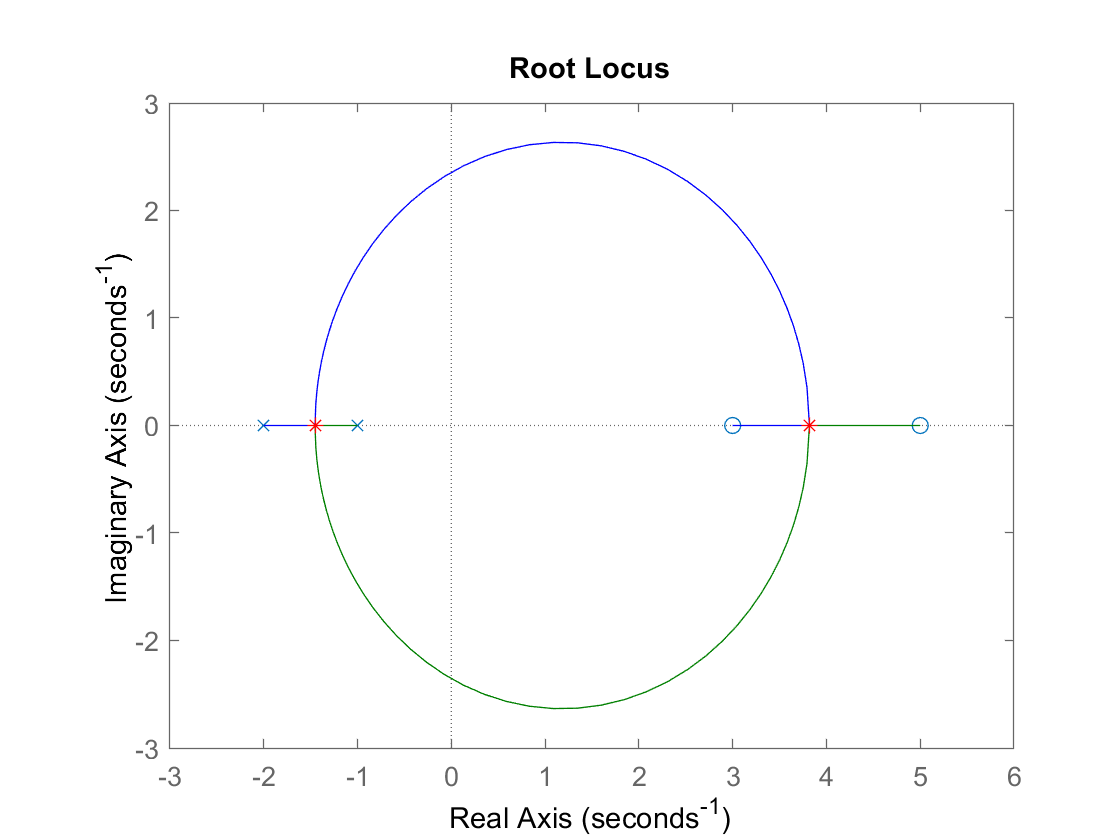

Current plot released


plot(complex(double(points)),'r*')
hold

**Method 2:**

Solve the following equation to find break-in and break-out points:


$$\Sigma_{i=1}^m\frac{1}{s+z_i}=\Sigma_{i=1}^n\frac{1}{s+p_i}$$


Where $z_i$ and $p_i$ are the negations of the open look poles and zeros of $G(s)H(s)$ respectively.

So for $G(s)=\frac{K(s-3)(s-5)}{(s+1)(s+2)}$ and $H(s)=1$ we get $\frac{1}{s-3}+\frac{1}{s-5}=\frac{1}{s+1}+\frac{1}{s+2}$

syms s 
breakPoints=solve(1/(s-3)+1/(s-5)==1/(s+1)+1/(s+2))

$$breakPoints = \left(\begin{array}{c} \frac{13}{11}-\frac{2\,\sqrt{210}}{11}\\ \frac{2\,\sqrt{210}}{11}+\frac{13}{11} \end{array}\right)$$

eval(breakPoints)

ans =    -1.4530
    3.8166


Same as before but without the differentiation step.

Now let's refine our root locus from the earlier example and find the break out point and $j\omega$ axis crossings of the systems:

clear
syms sigma s K 
Gs=(s+3)/(s*(s+1)*(s+2)*(s+4))

$$Gs = \frac{s+3}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$

eq1=1+K*Gs==0

$$eq1 = \frac{K\,\left(s+3\right)}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}+1=0$$

eq2=isolate(eq1,K)

$$eq2 = K=-\frac{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}{s+3}$$

points=solve(diff(rhs(eq2),1)==0)

$$points = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+\frac{26\,z^{3}}{3}+\frac{77\,z^{2}}{3}+28\,z+8 \end{array}$$

dK=diff(rhs(eq2),1)

$$dK = \frac{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}{{\left(s+3\right)}^{2}}-\frac{s\,\left(s+1\right)\,\left(s+2\right)}{s+3}-\frac{s\,\left(s+1\right)\,\left(s+4\right)}{s+3}-\frac{s\,\left(s+2\right)\,\left(s+4\right)}{s+3}-\frac{\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}{s+3}$$

simplifyFraction(dK)

$$ans = -\frac{3\,s^{4}+26\,s^{3}+77\,s^{2}+84\,s+24}{{\left(s+3\right)}^{2}}$$

points=roots([3 26 77 84 24])

points =   -3.3110 + 0.6812i
  -3.3110 - 0.6812i
  -1.6097 + 0.0000i
  -0.4349 + 0.0000i


G=zpk([-3],[0 -1 -2 -4],1)

G =
 
         (s+3)
  -------------------
  s (s+1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



angle(evalfr(G,points(3)))

ans = 0

Angle is not an odd multiple of $\pi$so $-1.6097$ is not a breakout/breakin point for $K>0$. It is actually a breakout point for a root locus $K<0$.

angle(evalfr(G,points(4)))

ans = 3.1416

Angle of $G(-0.4349)$ is $\pi$so it lies on the root locus as you can see in the figure below

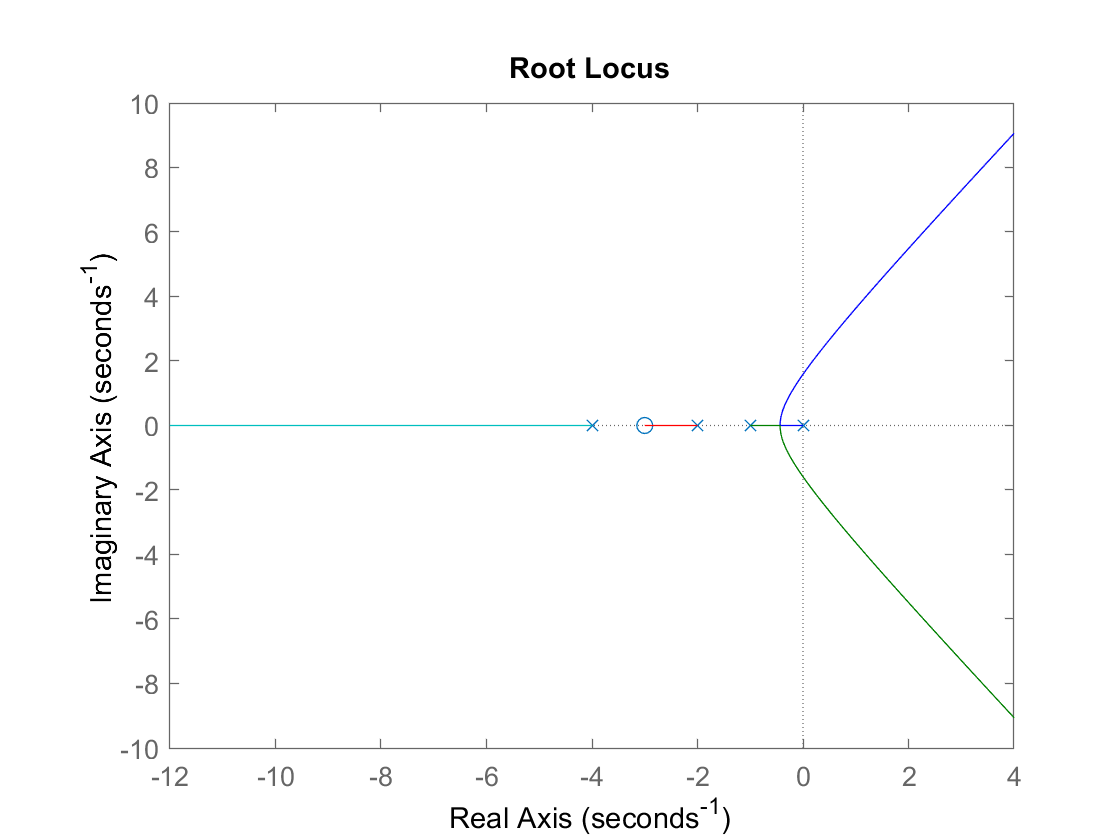

rlocus(G)

Gcls=K*Gs/(1+K*Gs)

$$Gcls = \frac{K\,\left(s+3\right)}{s\,\left(\frac{K\,\left(s+3\right)}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}+1\right)\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$

Gcls=collect(simplifyFraction(Gcls))

$$Gcls = \frac{K\,s+3\,K}{s^{4}+7\,s^{3}+14\,s^{2}+\left(K+8\right)\,s+3\,K}$$

RT=[s^4 1 14 3*K;s^3 7 K+8 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0 \end{array}\right)$$

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7}}{\frac{K}{7}-\frac{90}{7}} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \begin{array}{l} \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{\sigma_{1}}{\frac{K}{7}-\frac{90}{7}} & 0 & 0\\ 1 & \frac{3\,K\,\left(\frac{K}{7}-\frac{90}{7}\right)\,\left(K^{2}+65\,K-720\right)}{\left(K-90\right)\,\sigma_{1}} & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7} \end{array}$$

RT(4,2)=simplifyFraction(RT(4,2))

$$RT = \begin{array}{l} \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{\sigma_{1}}{K-90} & 0 & 0\\ 1 & \frac{3\,K\,\left(\frac{K}{7}-\frac{90}{7}\right)\,\sigma_{1}}{\left(K-90\right)\,\left(\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7}\right)} & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=K^{2}+65\,K-720 \end{array}$$

RT(5,2)=simplifyFraction(RT(5,2))

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{K^{2}+65\,K-720}{K-90} & 0 & 0\\ 1 & 3\,K & 0 & 0 \end{array}\right)$$

RT

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{K^{2}+65\,K-720}{K-90} & 0 & 0\\ 1 & 3\,K & 0 & 0 \end{array}\right)$$

soln=solve(K^2 + 65*K - 720==0)

$$soln = \left(\begin{array}{c} -\frac{7\,\sqrt{145}}{2}-\frac{65}{2}\\ \frac{7\,\sqrt{145}}{2}-\frac{65}{2} \end{array}\right)$$

eval(soln)

ans =   -74.6456
    9.6456


#### Solving for Method 1: Solving for $j\omega$ values for imaginary axis crossings by forcing a row of Routh Table to all zeros.

For the Routh Table

RT

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{K^{2}+65\,K-720}{K-90} & 0 & 0\\ 1 & 3\,K & 0 & 0 \end{array}\right)$$

for $K>0$ then only the $s^1$ row ca    n be forced to be zeros which we calculated up above as 

soln(2)

$$ans = \frac{7\,\sqrt{145}}{2}-\frac{65}{2}$$

 We can now finf the roots of the polynomial from the row preceding the zeroed row, ie. the $s^2$ row to get the $j\omega$ axis crossings.

eqRow2=(90-K)*s^2+21*K==0

$$eqRow2 = 21\,K-s^{2}\,\left(K-90\right)=0$$

eqRow2=subs(eqRow2,K,soln(2))

$$eqRow2 = \left(\frac{245}{2}-\frac{7\,\sqrt{145}}{2}\right)\,s^{2}+\frac{147\,\sqrt{145}}{2}-\frac{1365}{2}=0$$

omegas=solve(eqRow2,s)

$$omegas = \left(\begin{array}{c} -\sqrt{-\frac{\frac{147\,\sqrt{145}}{2}-\frac{1365}{2}}{\frac{7\,\sqrt{145}}{2}-\frac{245}{2}}}\,\mathrm{i}\\ \sqrt{-\frac{\frac{147\,\sqrt{145}}{2}-\frac{1365}{2}}{\frac{7\,\sqrt{145}}{2}-\frac{245}{2}}}\,\mathrm{i} \end{array}\right)$$

eval(omegas)

ans =    0.0000 - 1.5877i
   0.0000 + 1.5877i


#### Method 2: Setting closed loop denominator to zero for value of $K$ that makes system unstable

Gclw=collect(subs(Gcls,K,soln(2)),s)

$$Gclw = \frac{\left(7\,\sqrt{145}-65\right)\,s+21\,\sqrt{145}-195}{2\,s^{4}+14\,s^{3}+28\,s^{2}+\left(7\,\sqrt{145}-49\right)\,s+21\,\sqrt{145}-195}$$

syms omega 
Gclw=subs(Gclw,s,1i*omega)

$$Gclw = \frac{21\,\sqrt{145}-195+\omega \,\left(7\,\sqrt{145}-65\right)\,\mathrm{i}}{21\,\sqrt{145}-28\,\omega^{2}+2\,\omega^{4}-195-14\,\omega^{3}\,\mathrm{i}+\omega \,\left(7\,\sqrt{145}-49\right)\,\mathrm{i}}$$

[n,d]=numden(Gcls)

$$n = 3\,K+K\,s$$

$$d = 3\,K+8\,s+K\,s+14\,s^{2}+7\,s^{3}+s^{4}$$

d=collect(d)

$$d = s^{4}+7\,s^{3}+14\,s^{2}+\left(K+8\right)\,s+3\,K$$

subs(d,s,j*omega)

$$ans = 3\,K-14\,\omega^{2}+\omega^{4}+\omega \,\left(K+8\right)\,\mathrm{i}-7\,\omega^{3}\,\mathrm{i}$$

Both the real and the imaginary parts of this equation must be zero for the value of $j\omega$ to be on the root locus (i.e. a closed loop pole means the demoninator polynomial is zero at that value - assuming no pole zero cancellation) when $K$ takes on the value that makes the system that goes unstable for $K>0$ from the Routh table, i.e..

soln(2)

$$ans = \frac{7\,\sqrt{145}}{2}-\frac{65}{2}$$

is the value of $K$ from above.

First let's solve for the values of $j\omega$ that make the imaginary part zero, i.e. $j[(K+8)\omega-7\omega^3]=j0$  

imagZero=eval(subs(solve((K+8)*omega-7*omega^3==0),K,soln(2)))

imagZero =          0
   -1.5877
    1.5877


We get three possible values. Let's solve the values of $j\omega$ that make the real part of the denominator zero:

realZero=eval(subs(solve(omega^4- 14*omega^2+3*K==0),K,soln(2)))

realZero =     3.3881
   -3.3881
    1.5877
   -1.5877


We see that only the values of $j\omega=\pm j 1.5877$ make both the real and imaginary parts zero so that must be the value on the imaginary axis that the RL crosses into the Right Half Plane (RHP) to become unstable.

omegaValues=intersect(round(imagZero,12),round(realZero,12))
rlocus(G)
hold
plot(j*omegaValues,'r*')
plot(complex(points(4)),'c*')
hold

## 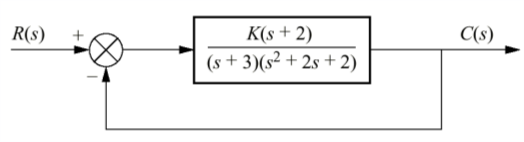

G8_16=zpk([-2],[-3 -1-j -1+j],1)

G8_16 =
 
         (s+2)
  --------------------
  (s+3) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.



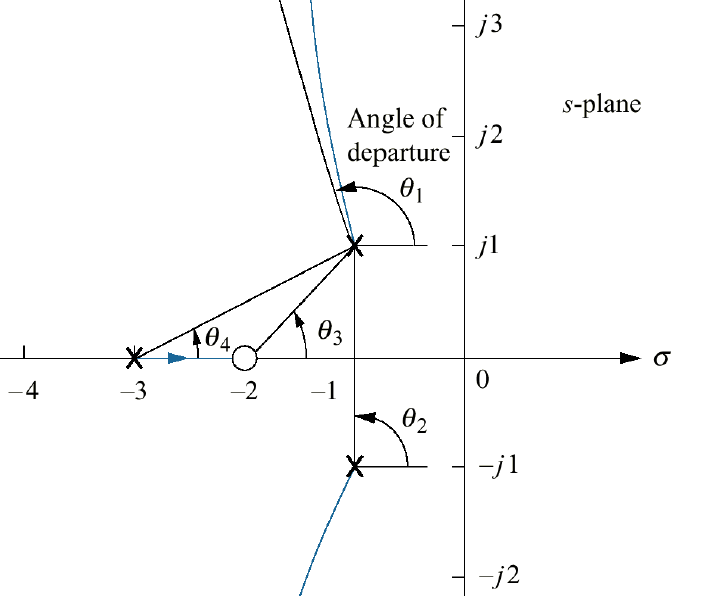

From the above diagram we are trying to compute the departure angle $\theta_1$ from the pole at $s=-p_1=-1+j$. For the departure point $s=-1+j+\epsilon$ to lie on the root locus we must have:

$1+KG(s)=0$ or equivalently $KG(s)=-1$ which implies $\angle G(s)=(2k+1)\pi$rad. From the diagram this means that:

$-\theta_1-\theta_2+\theta_3-\theta_4=(2k+1)\pi$, or equivalently


$$\theta_1=-\theta_2+\theta_3-\theta_4-(2k+1)\pi$$


where the angle $\theta_i$ is the angle from pole or zero $i$ to the point $s=-1+j+\epsilon$, but for $|\epsilon|\approx  0$ (small values of $\epsilon$) $\theta_i$ is approximately the same as the angle to $-1+j$.  So:


$$-\theta_2+\theta_3-\theta_4\approx \angle\left .\frac{(s+2)}{(s+1+j)(s+3)}\right|_{s=-1+j}=\angle\left .\frac{(1+j)}{(j2)(2+j)}\\
=\angle\frac{1+j}{-2+j4}\\
=\angle\frac{1+j}{-2+j4}\times\frac{-2-j4}{-2-j4}\\
=\angle\frac{2-j6}{20}=\angle ({\frac{1}{10}-j\frac{3}{10} )$$


We can numerically evaluate this in matlab as:

G8_16angle=zpk([-2],[-3 -1-j],1)

G8_16angle =
 
       (s+2)
  ----------------
  (s+3) (s+(1+1i))
 
Continuous-time zero/pole/gain model.



value=evalfr(G8_16angle, -1+j)

value = 0.1000 - 0.3000i

angle(value)

ans = -1.2490

Taking $k=-1$ in $\theta_1=-\theta_2+\theta_3-\theta_4-(2k+1)\pi$ we get

theta_1=angle(value)+pi

theta_1 = 1.8925

(angle(value)+pi)*180/pi

ans = 108.4349

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=(s+2)/((s+3)*(s^2+2*s+2))

G =
 
          s + 2
  ---------------------
  s^3 + 5 s^2 + 8 s + 6
 
Continuous-time transfer function.



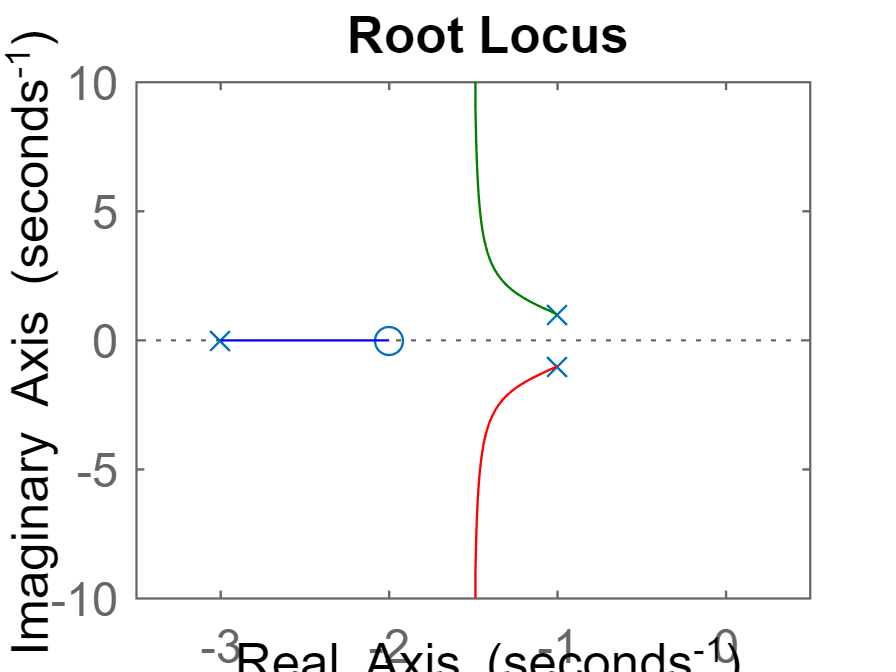

rlocus(G)

### Third-order System Gain Design Example

For system below, design the value of gain, $K$, that will give 1.52% overshoot. Also estimate the settling time, peak time, and steady-state error.

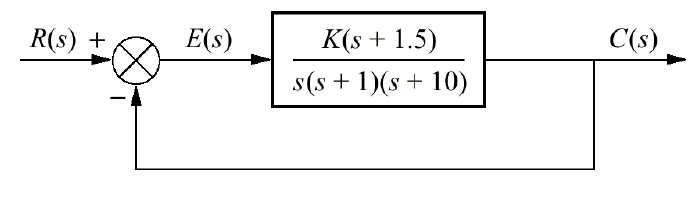

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=zpk([-1.5],[0 -1 -10],1)

G =
 
     (s+1.5)
  --------------
  s (s+1) (s+10)
 
Continuous-time zero/pole/gain model.



pos=1.52

pos = 1.5200

zeta=-log(pos/100)/sqrt(pi^2+(log(pos/100))^2)

zeta = 0.7998

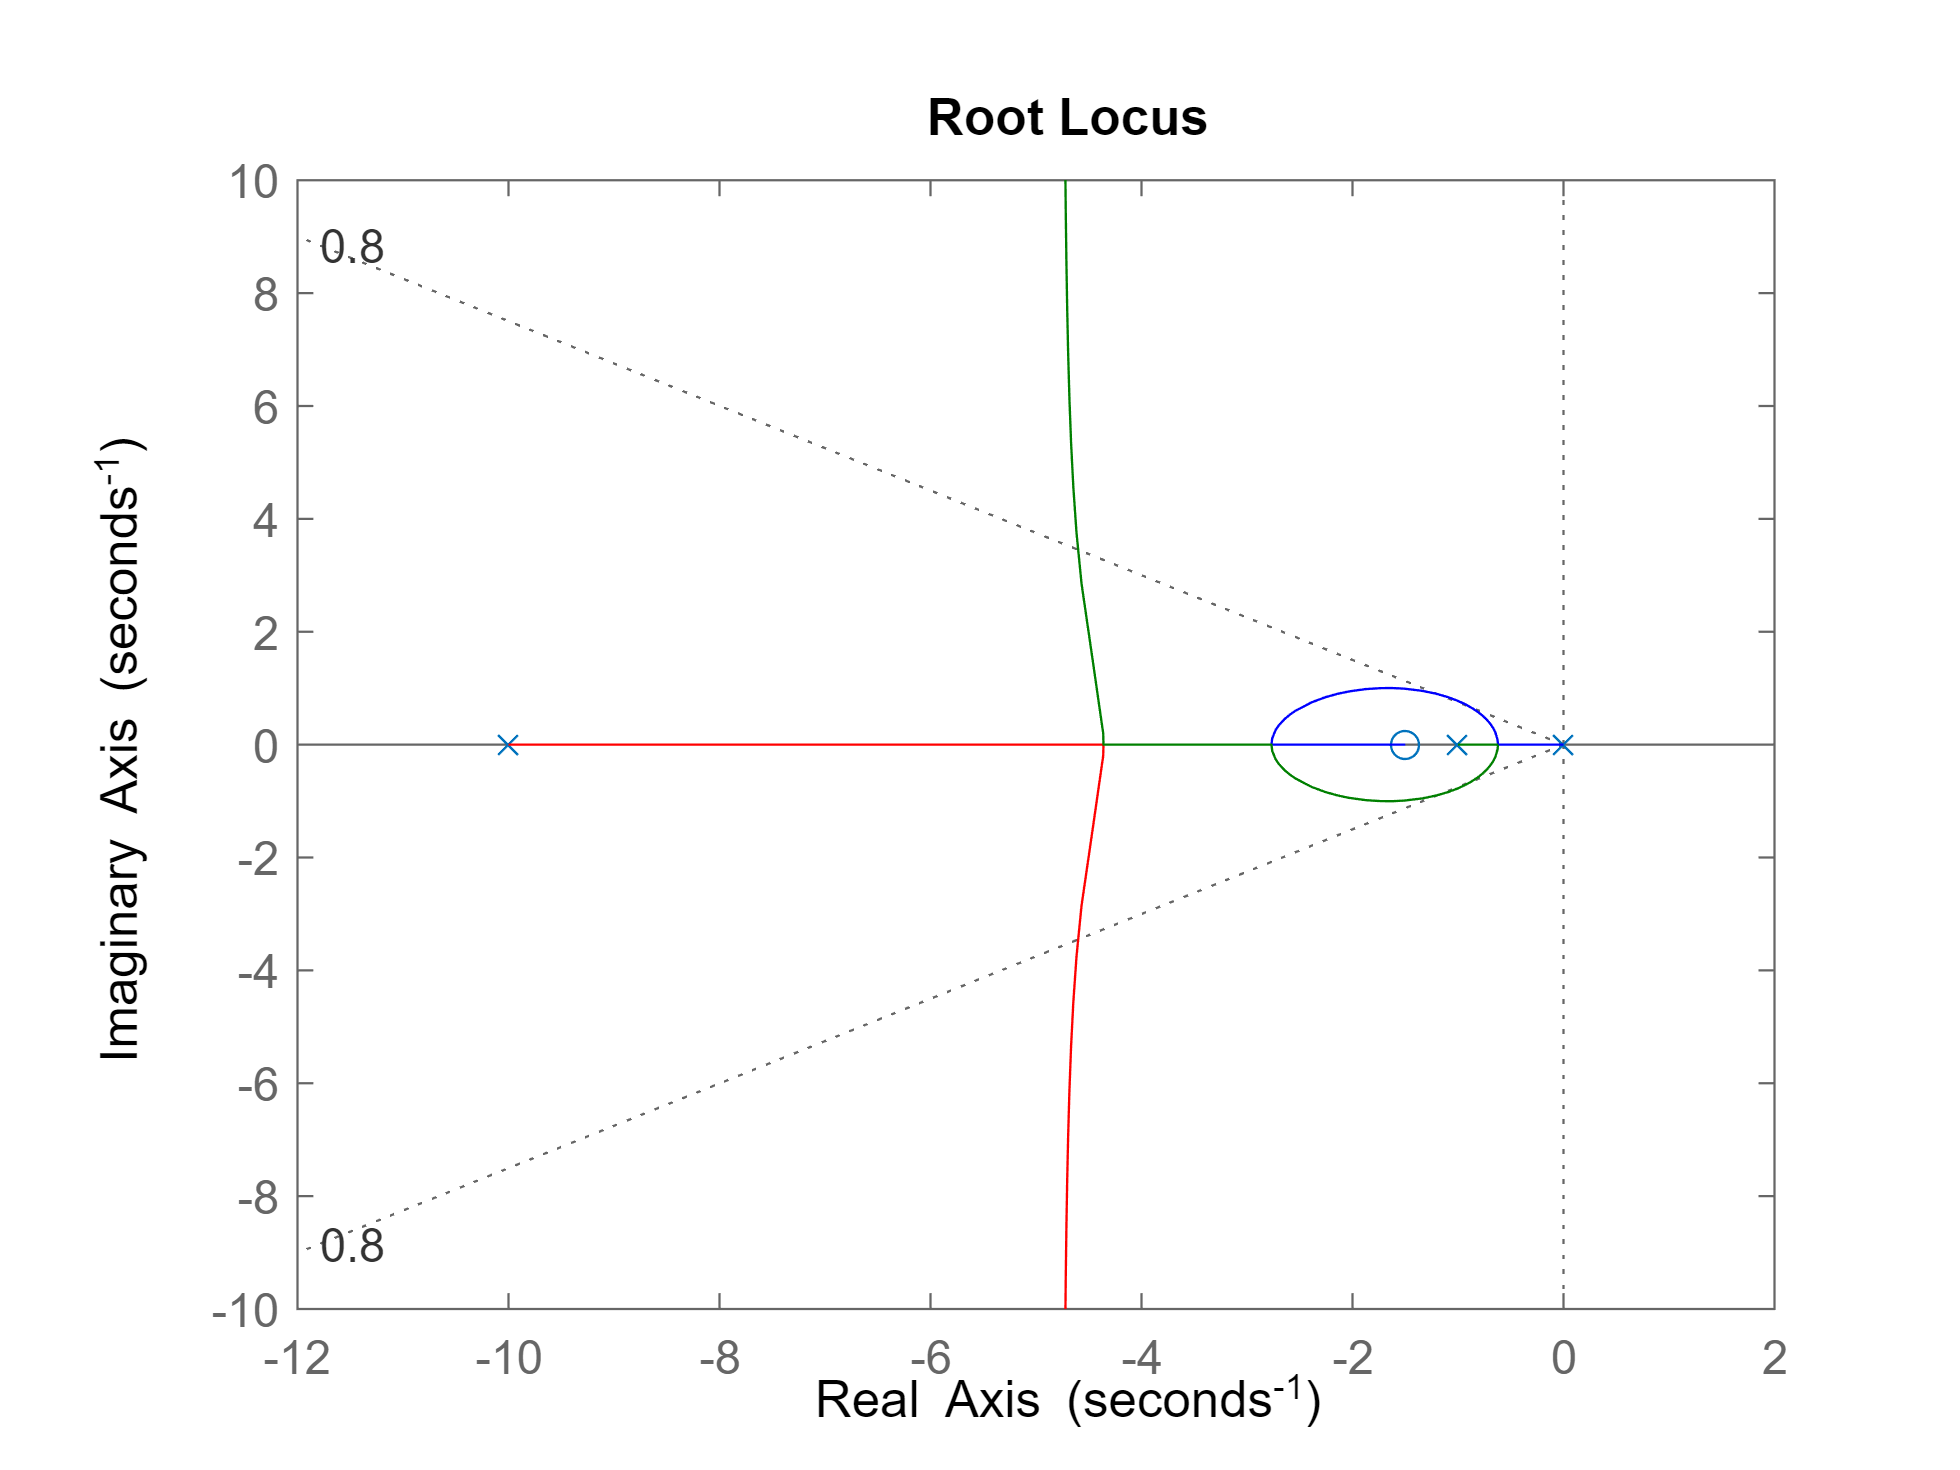

rlocus(G)
sgrid(zeta,0)

s1=-.87+j*.66

s1 = -0.8700 + 0.6600i

K1=1/abs(evalfr(G,s1))

K1 = 7.3697

s2=-1.19+j*.90

s2 = -1.1900 + 0.9000i

K2=1/abs(evalfr(G,s2))

K2 = 12.7681

s3=-4.6+j*3.45

s3 = -4.6000 + 3.4500i

K3=1/abs(evalfr(G,s3))

K3 = 39.6112

Gcl1=feedback(K1*G,1)

Gcl1 =
 
           7.3697 (s+1.5)
  --------------------------------
  (s+9.252) (s^2 + 1.748s + 1.195)
 
Continuous-time zero/pole/gain model.



Gcl2=feedback(K2*G,1)

Gcl2 =
 
           12.768 (s+1.5)
  --------------------------------
  (s+8.615) (s^2 + 2.385s + 2.223)
 
Continuous-time zero/pole/gain model.



Gcl3=feedback(K3*G,1)

Gcl3 =
 
           39.611 (s+1.5)
  --------------------------------
  (s+1.796) (s^2 + 9.204s + 33.08)
 
Continuous-time zero/pole/gain model.



p1=pole(Gcl1)

p1 =   -9.2517 + 0.0000i
  -0.8742 + 0.6563i
  -0.8742 - 0.6563i


p2=pole(Gcl2)

p2 =   -8.6153 + 0.0000i
  -1.1924 + 0.8952i
  -1.1924 - 0.8952i


p3=pole(Gcl3)

p3 =   -1.7962 + 0.0000i
  -4.6019 + 3.4499i
  -4.6019 - 3.4499i


Let's plot the step response of our design choice with gain $K_2$ and compare it with the ideal 2nd order system with poles at that location so we can see the effects of the 3rd pole and the zero on the actual system.

step(Gcl2)
G2cl2nd=zpk([],[s2 s2'],s2*s2')

G2cl2nd =
 
         2.2261
  ---------------------
  (s^2 + 2.38s + 2.226)
 
Continuous-time zero/pole/gain model.



hold

Current plot held


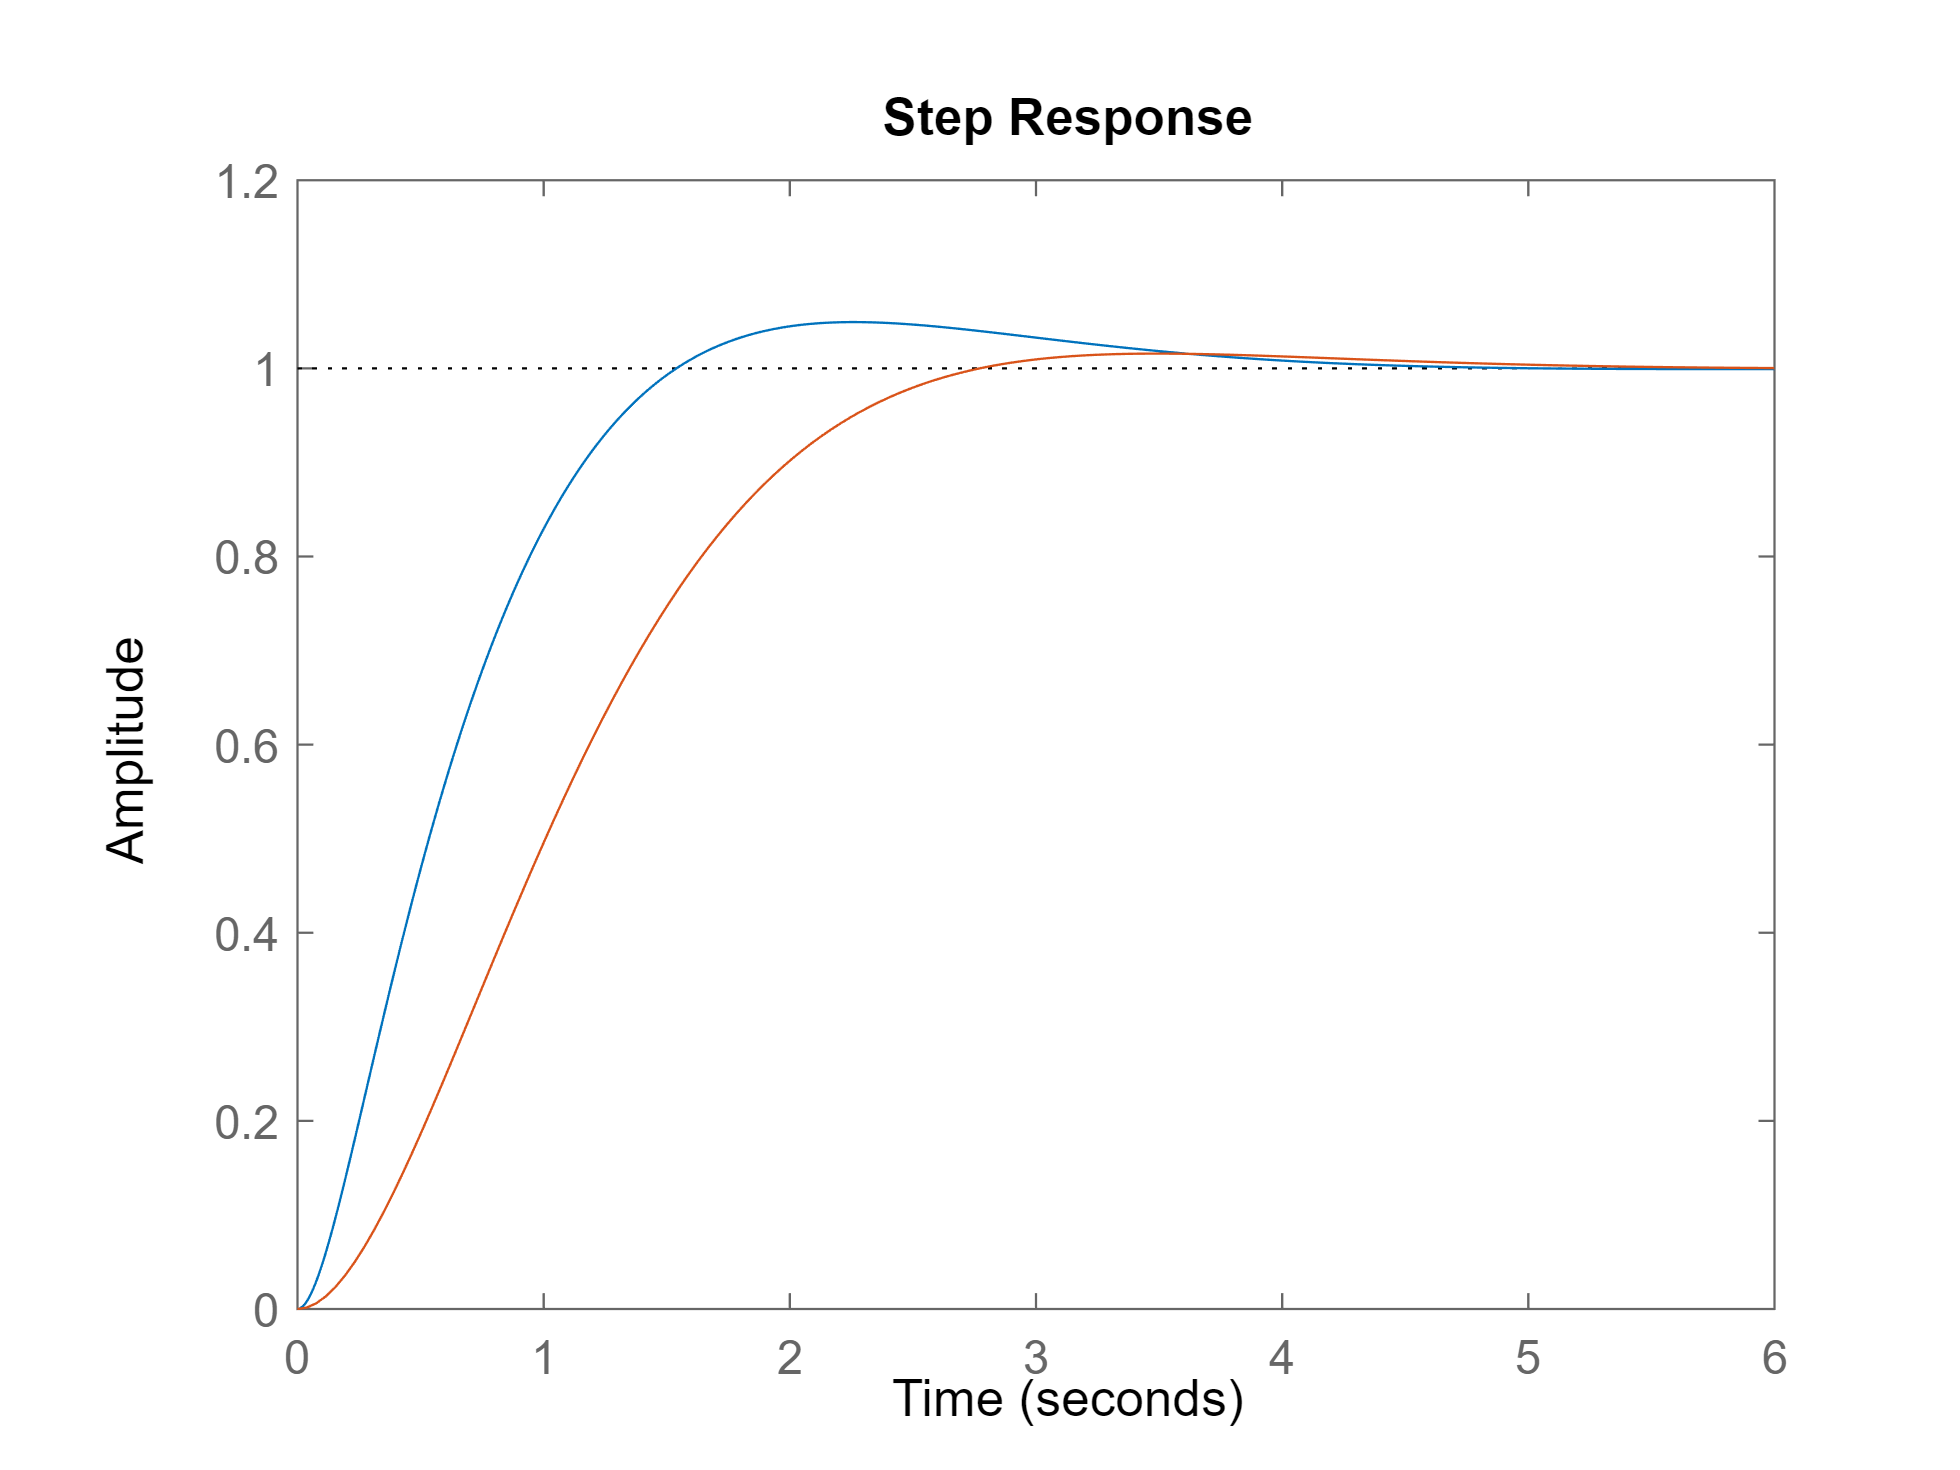

Current plot released


step(G2cl2nd)
hold

rlocus(G)
sgrid(zeta,0)
hold

Current plot held


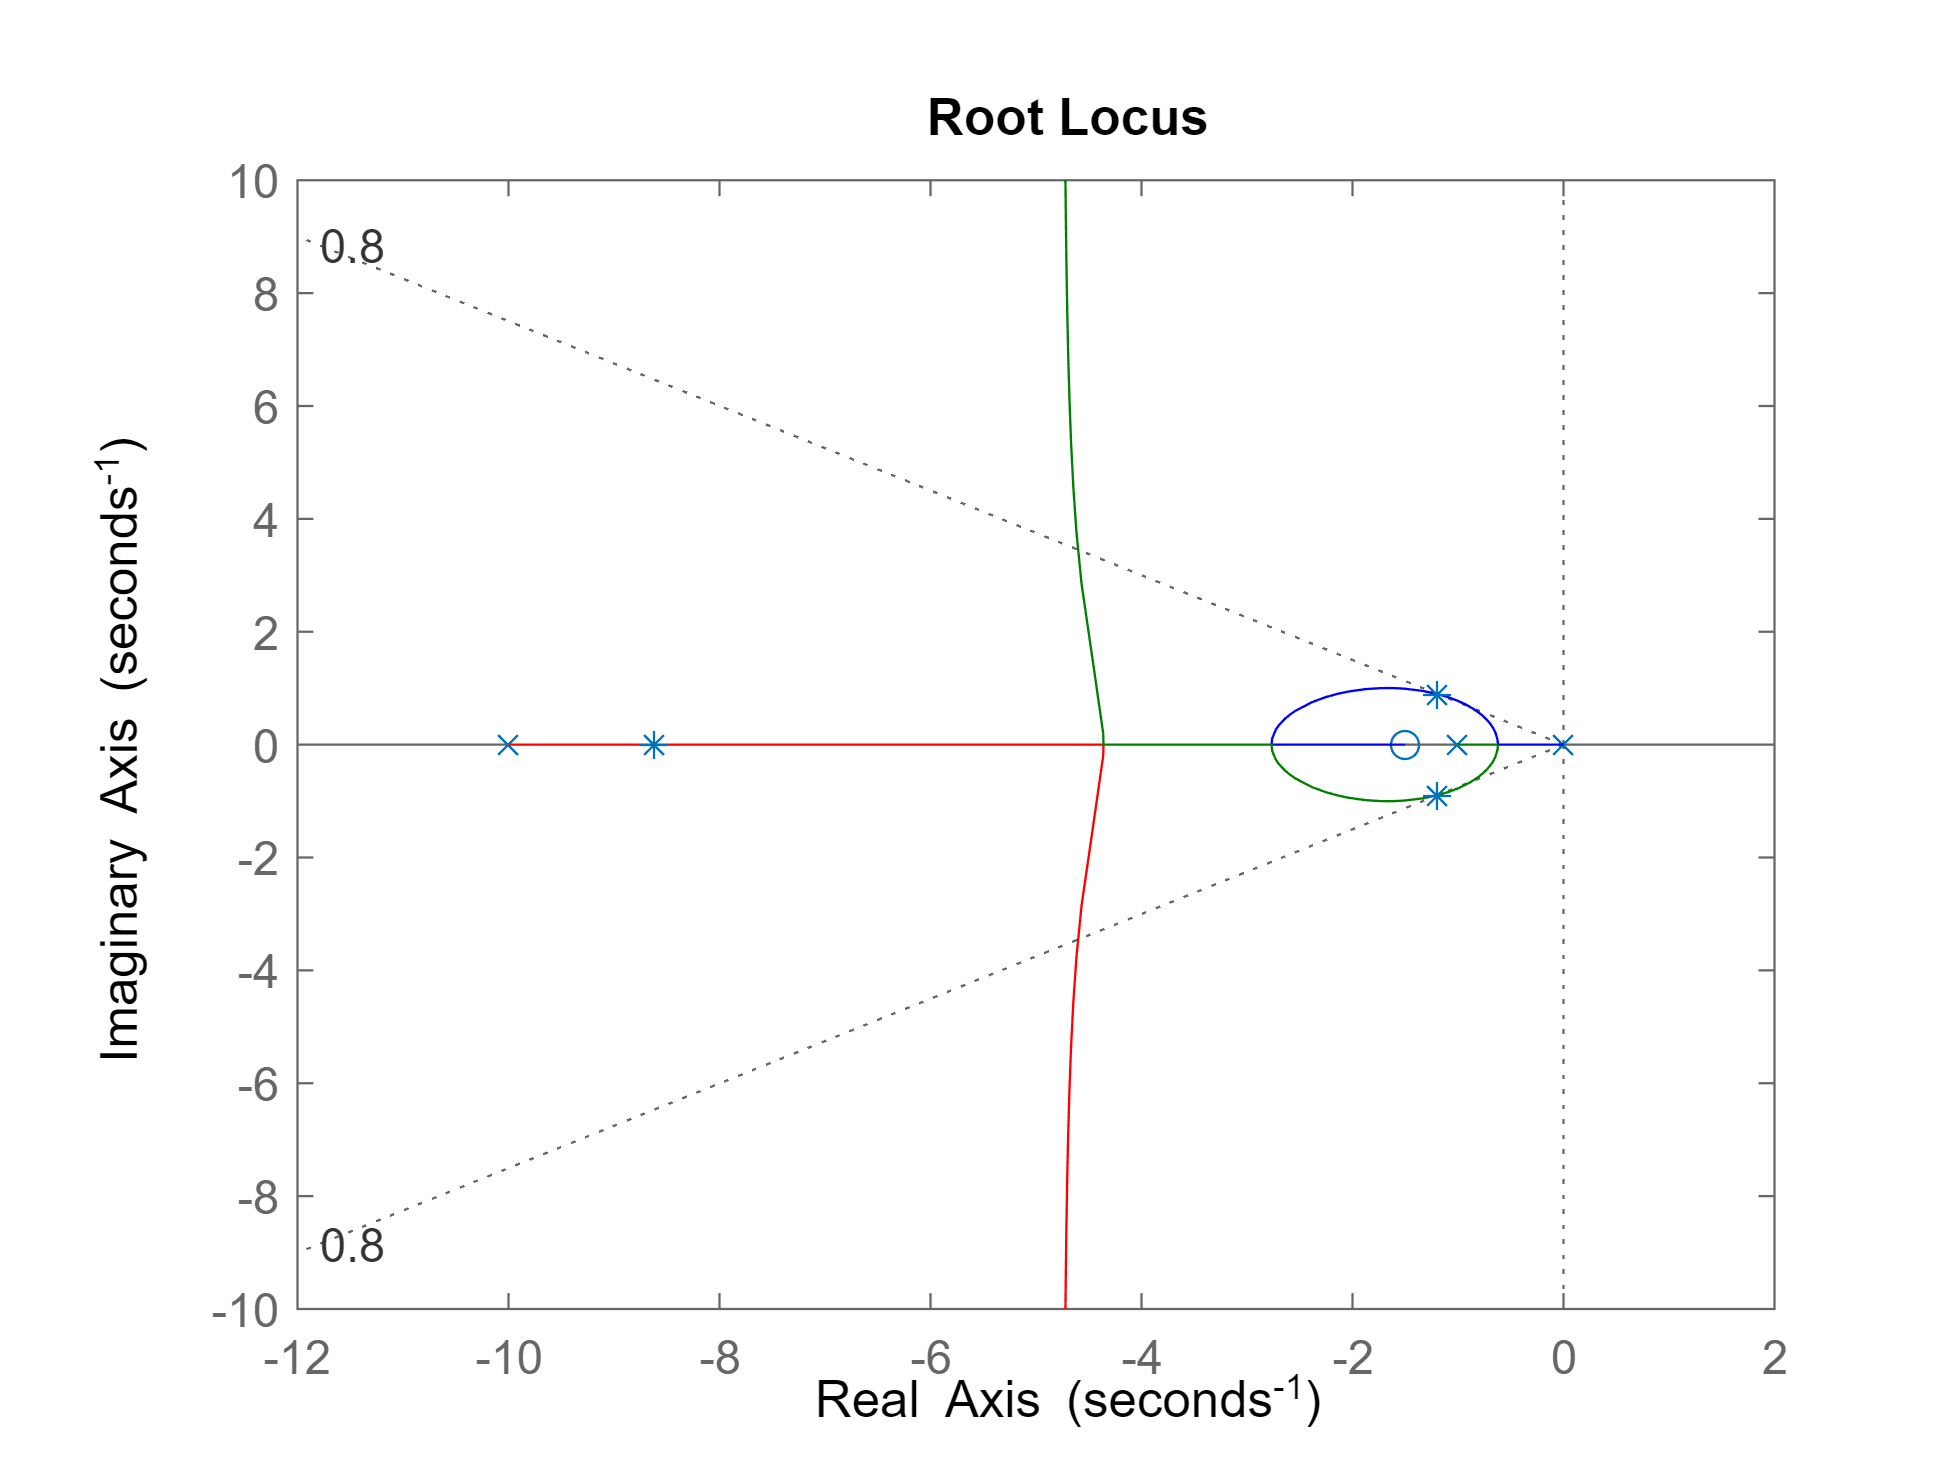

Current plot released


plot(p2,'*')
hold

Let's see how the closed loop systems respond to a ramp  input

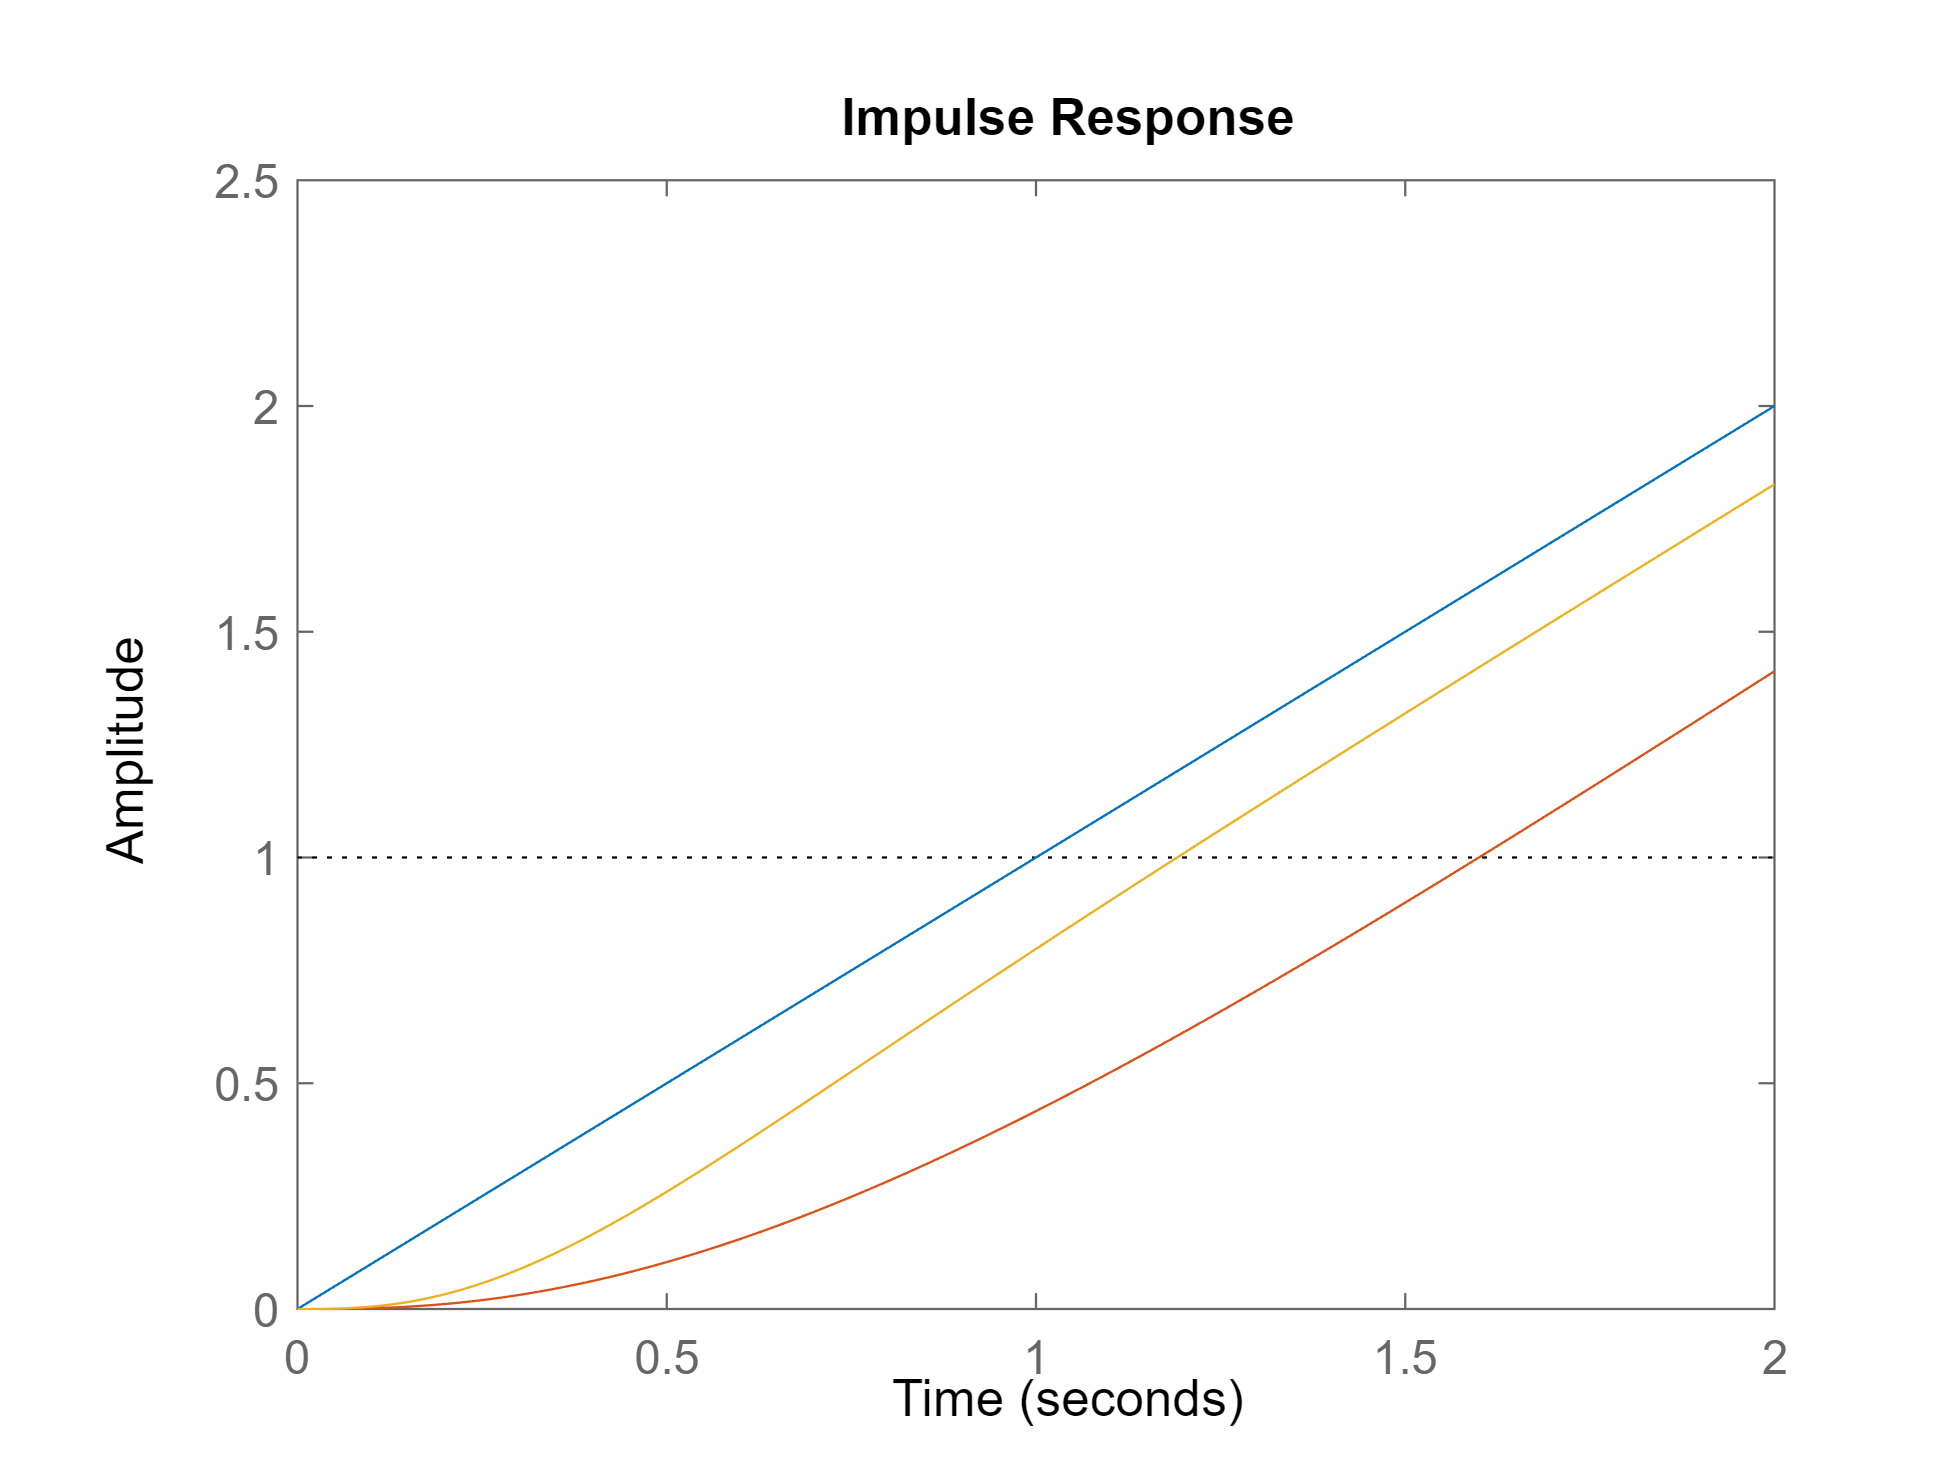

impulse(1/s^2,Gcl2/s^2,Gcl3/s^2,2)

Steady state error for a Type 1 system is given by $e(\infty)=\frac{1/K_v}$

Kv3=evalfr(minreal(s*K3*G),0)

Kv3 = 5.9417

ess3=1/Kv3

ess3 = 0.1683

Kv2=evalfr(minreal(s*K2*G),0)

Kv2 = 1.9152

ess2=1/Kv2

ess2 = 0.5221

How does this compare with the plot?

Now let's plot the error times the gain $K$ for each systems. This lets us compute the output of the proportional contoller $u(t)=K\,e(t)$ for each fo the systems in response to a step input:

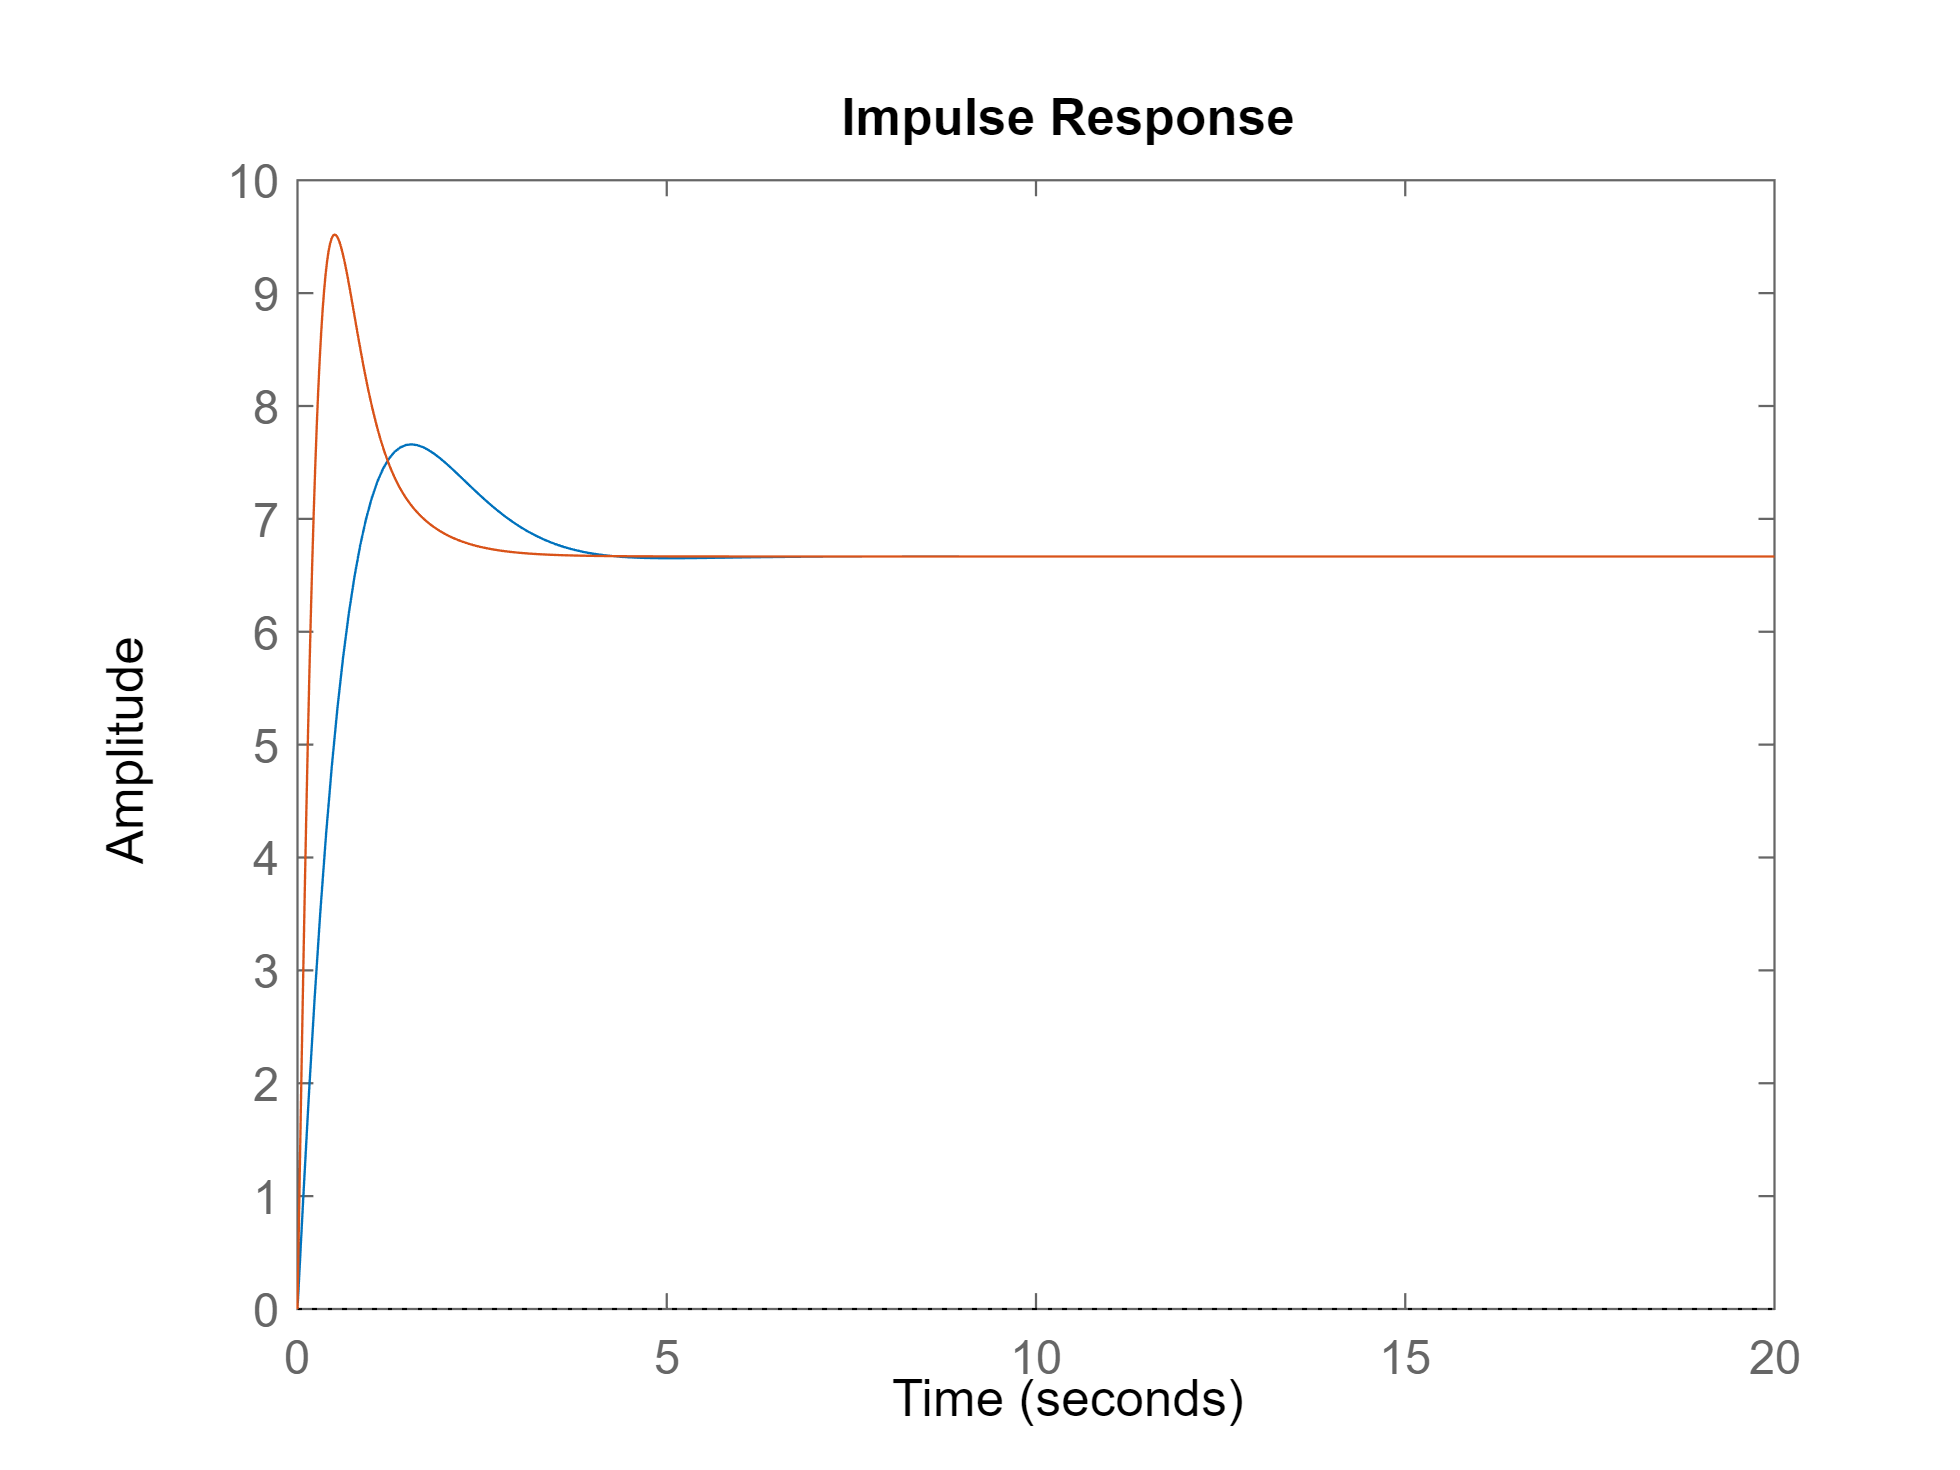

impulse(K2*(1/s^2-Gcl2/s^2),K3*(1/s^2-Gcl3/s^2),20)